# Monovariate Linear Regression

## Introduction

The file data1.txt contains the dataset for our linear regression problem. 

The first column represents the population of a city and the second column is the profit of a food truck in that city.

A negative value for profit indicates a loss.

Using the Batch Gradient Descent we will extimate a Linear Regression.

### Data Loading and Representation

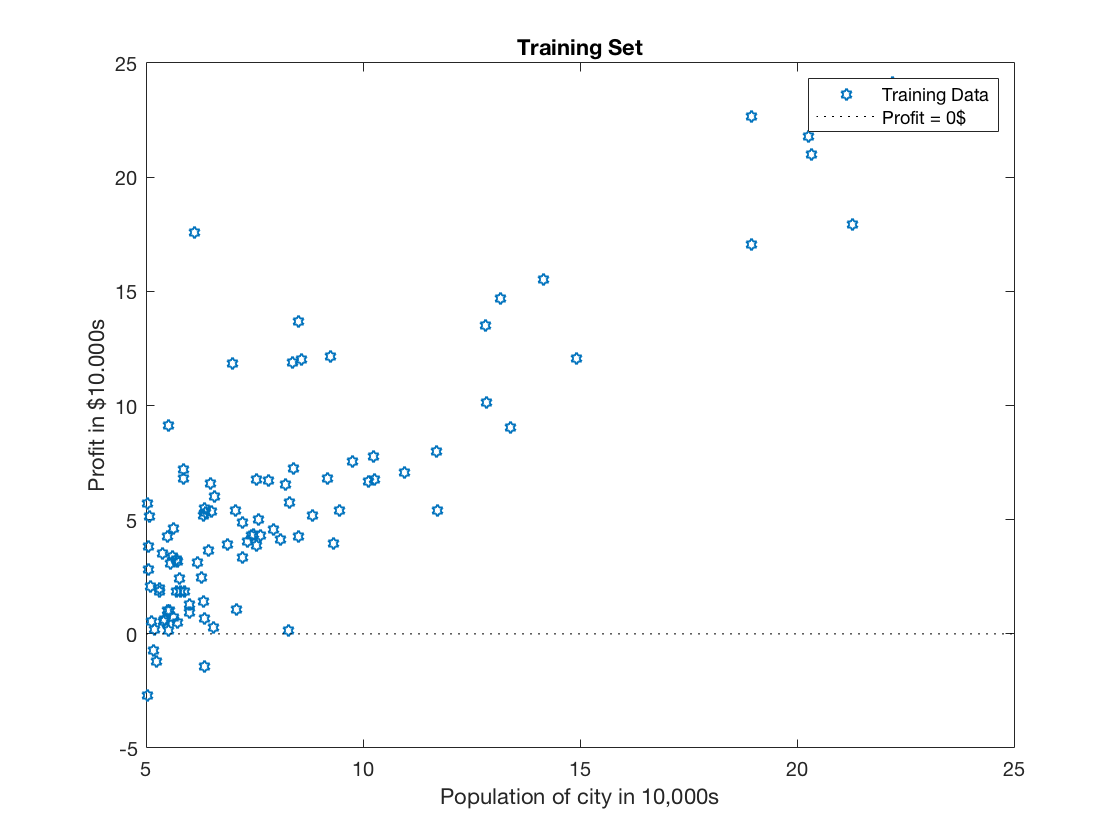

B = load('./data1.txt');
[m, n1] = size(B);
n = n1 - 1;
X = B(:, 1:n);
Y = B(:, n1);
plot(X, Y, 'h', [5 25], [0 0], ':k');
title('Training Set');
xlabel('Population of city in 10,000s');
ylabel('Profit in $10.000s');
legend('Training Data', 'Profit = 0$');

### Correctness Check

Xo = [ones(1, m);X']';
assert(round(linear_cost(Xo, Y, [0 ; 0]), 2) == 32.07);
assert(round(linear_cost(Xo, Y, [-1; 2]), 2) == 54.24);

## Batch Gradient Descent Function

Let's evaluate the Batch Gradient Descent Function over different $\alpha$ values and 1500 iterations.

For each value the function will output different premonition functions $h_\theta(x) = X_0 \times \theta$.

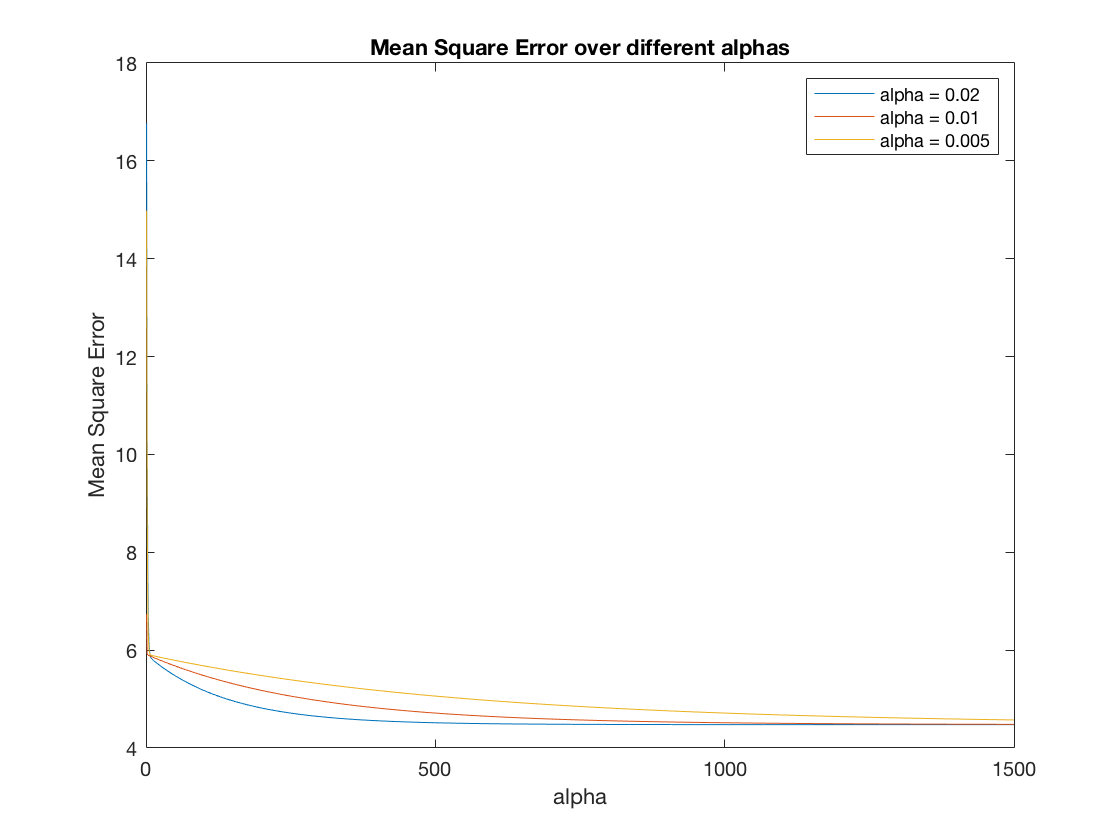

[theta02, J02] = linear_gradient_descend(Xo, Y, [0 ; 0], 0.02, 1500);
[theta01, J01] = linear_gradient_descend(Xo, Y, [0 ; 0], 0.01, 1500);
[theta005, J005] = linear_gradient_descend(Xo, Y, [0 ; 0], 0.005, 1500);

plot([J02 J01 J005]);
title('Mean Square Error over different alphas')
xlabel('alpha');
ylabel('Mean Square Error');
legend({'alpha = 0.02','alpha = 0.01','alpha = 0.005'})

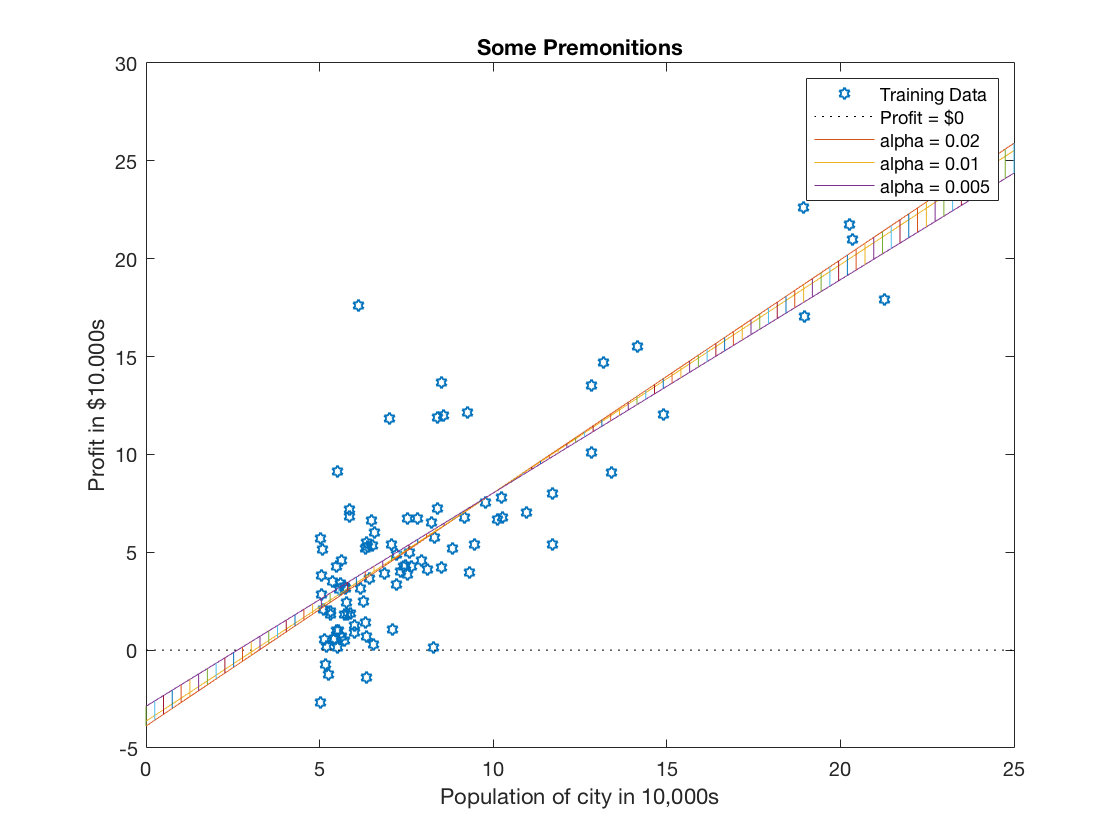

x = linspace(0, 25);
y02 = x*theta02(2) + theta02(1);
y01 = x*theta01(2) + theta01(1);
y005 = x*theta005(2) + theta005(1);

plot(X, Y, 'h');
hold on;
plot([0 25], [0 0], ':k');
plot(x, y02);
plot(x, y01);
plot(x, y005);
plot([x;x;x], [y02;y01;y005]);
hold off;
title('Some Premonitions')
xlabel('Population of city in 10,000s');
ylabel('Profit in $10.000s');
legend('Training Data', 'Profit = $0', 'alpha = 0.02','alpha = 0.01','alpha = 0.005');

## Optimal Prediction

We can avoid using a User-Defined Gradient Descent function. MatLab offers a powerful function, namely `fminunc`.

By using this function we can evaluate the optimal $h_\theta(x) = X_0 \times \theta$ and we can use it to predict some values.

options = optimset('GradObj', 'on', 'MaxIter', 100);
[opt_theta, opt_cost, exit_flag] = fminunc(@(t)(linear_cost(Xo, Y, t)), [0;0], options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


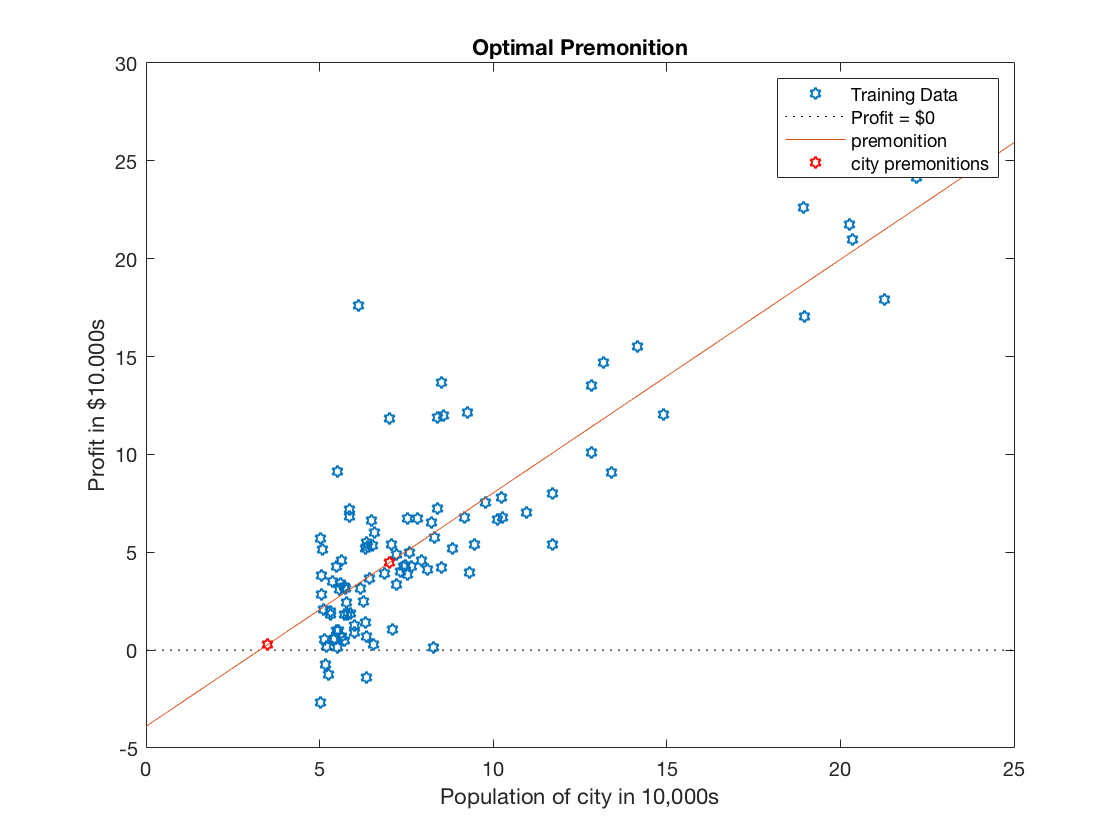

X_prem = [3.5; 7];
Xo_prem = [ones(2, 1) X_prem];
Y_prem = Xo_prem * opt_theta;
x = [linspace(1, 1)' linspace(0, 25)'];
y = x * opt_theta;
plot(X, Y, 'h');
hold on;
plot([0 25], [0 0], ':k');
plot(linspace(0, 25), y);
plot(X_prem, Y_prem, 'hr');
hold off;
title('Optimal Premonition');
xlabel('Population of city in 10,000s');
ylabel('Profit in $10.000s');
legend('Training Data', 'Profit = $0', 'premonition','city premonitions');